# RawMotion2Motion

## 0. Import raw data with error handling

clc;
clear;

try
    T = readtable("./RawData/RawMotion.csv");
    fprintf('✓ Successfully loaded RawMotion.csv\n');
catch ME
    error('Failed to load ChewSwallow.csv: %s', ME.message);
end

✓ Successfully loaded RawMotion.csv



% Extract marker coordinates with validation
required_cols = {'Frontal_x', 'Frontal_y', 'Frontal_z', 'Nasal_x', 'Nasal_y', 'Nasal_z', ...
                 'Maxilla_x', 'Maxilla_y', 'Maxilla_z', 'Mandible_x', 'Mandible_y', 'Mandible_z', ...
                 'ThyCart_x', 'ThyCart_y', 'ThyCart_z'};

% Check if all required columns exist
missing_cols = setdiff(required_cols, T.Properties.VariableNames);
if ~isempty(missing_cols)
    error('Missing columns: %s', strjoin(missing_cols, ', '));
end

Frontal = table2array(T(:, {'Frontal_x', 'Frontal_y', 'Frontal_z'}));
Nasal = table2array(T(:, {'Nasal_x', 'Nasal_y', 'Nasal_z'}));
Maxilla = table2array(T(:, {'Maxilla_x', 'Maxilla_y', 'Maxilla_z'}));
Mandible = table2array(T(:, {'Mandible_x', 'Mandible_y', 'Mandible_z'}));
ThyCart = table2array(T(:, {'ThyCart_x', 'ThyCart_y', 'ThyCart_z'}));

FsMotion = 59.94;
[num_points, ~] = size(Frontal);
tMotion = (0:num_points-1) / FsMotion;

fprintf('Data info: %d frames, %.2f seconds, %.2f Hz\n', num_points, tMotion(end), FsMotion);

Data info: 5037 frames, 84.02 seconds, 59.94 Hz


clear T;

## 0.5. Data Quality Check & Outlier Detection

markers = {'Frontal', 'Nasal', 'Maxilla', 'Mandible', 'ThyCart'};
marker_data = {Frontal, Nasal, Maxilla, Mandible, ThyCart};

fprintf('\n=== Data Quality Assessment ===\n');


=== Data Quality Assessment ===


outlier_indices = [];

for m = 1:length(markers)
    data = marker_data{m};
    
    % Check for missing values (NaN)
    nan_count = sum(isnan(data(:)));
    if nan_count > 0
        fprintf('⚠ Warning: %s has %d NaN values\n', markers{m}, nan_count);
    end
    
    % Detect outliers using modified z-score
    for dim = 1:3
        coords = ['XYZ'];
        signal = data(:, dim);
        
        % Remove NaN for outlier detection
        valid_idx = ~isnan(signal);
        if sum(valid_idx) < length(signal)
            fprintf('⚠ Warning: %s-%s has missing data\n', markers{m}, coords(dim));
        end
        
        % Calculate modified z-score
        median_val = median(signal(valid_idx));
        mad_val = median(abs(signal(valid_idx) - median_val));
        modified_z = 0.6745 * (signal - median_val) / mad_val;
        
        % Identify outliers (threshold = 3.5)
        outliers = abs(modified_z) > 5;
        outlier_count = sum(outliers);
        
        if outlier_count > 0
            fprintf('⚠ Warning: %s-%s has %d outliers (%.1f%)\n', ...
                markers{m}, coords(dim), outlier_count, 100*outlier_count/length(signal));
            outlier_indices = [outlier_indices; find(outliers)];
        end
    end
end

⚠ Warning: Nasal-X has 65 outliers (1.3⚠ Warning: ThyCart-X has 32 outliers (0.6⚠ Warning: ThyCart-Z has 18 outliers (0.4


% Remove duplicate outlier indices
outlier_indices = unique(outlier_indices);
fprintf('Total outlier frames detected: %d\n', length(outlier_indices));

Total outlier frames detected: 114


## 1. Interpolation for Missing Data

fprintf('\n=== Data Interpolation ===\n');


=== Data Interpolation ===



% Function to interpolate missing/outlier data
function interpolated_data = interpolate_marker_data(data, outlier_idx, t)
    interpolated_data = data;
    
    for dim = 1:3
        signal = data(:, dim);
        
        % Mark outliers as NaN
        signal(outlier_idx) = NaN;
        
        % Find valid data points
        valid_idx = ~isnan(signal);
        
        if sum(valid_idx) < length(signal)
            % Interpolate missing values
            interpolated_data(:, dim) = interp1(t(valid_idx), signal(valid_idx), t, 'pchip', 'extrap');
        end
    end
end

% Apply interpolation to all markers
Frontal_clean = interpolate_marker_data(Frontal, outlier_indices, tMotion);
Nasal_clean = interpolate_marker_data(Nasal, outlier_indices, tMotion);
Maxilla_clean = interpolate_marker_data(Maxilla, outlier_indices, tMotion);
Mandible_clean = interpolate_marker_data(Mandible, outlier_indices, tMotion);
ThyCart_clean = interpolate_marker_data(ThyCart, outlier_indices, tMotion);

fprintf('✓ Data interpolation completed\n');

✓ Data interpolation completed


## 2. Analyze frequency content of clean data

fprintf('\n=== Frequency Analysis ===\n');


=== Frequency Analysis ===


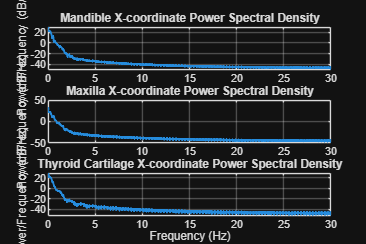


figure('Name', 'Frequency Analysis', 'Position', [100, 100, 1200, 800]);

% Create subplots for different markers
subplot(3,1,1);
[pxx_mandible, f] = pwelch(detrend(Mandible_clean(:,1)), [], [], [], FsMotion);
plot(f, 10*log10(pxx_mandible), 'LineWidth', 1.5);
title('Mandible X-coordinate Power Spectral Density');
ylabel('Power/Frequency (dB/Hz)');
xlim([0 30]); % Focus on relevant frequency range
grid on;

subplot(3,1,2);
[pxx_maxilla, ~] = pwelch(detrend(Maxilla_clean(:,1)), [], [], [], FsMotion);
plot(f, 10*log10(pxx_maxilla), 'LineWidth', 1.5);
title('Maxilla X-coordinate Power Spectral Density');
ylabel('Power/Frequency (dB/Hz)');
xlim([0 30]);
grid on;

subplot(3,1,3);
[pxx_thycart, ~] = pwelch(detrend(ThyCart_clean(:,1)), [], [], [], FsMotion);
plot(f, 10*log10(pxx_thycart), 'LineWidth', 1.5);
title('Thyroid Cartilage X-coordinate Power Spectral Density');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
xlim([0 30]);
grid on;


% Suggest cutoff frequency based on 95% power content
cumulative_power = cumsum(pxx_mandible) / sum(pxx_mandible);
cutoff_95_idx = find(cumulative_power >= 0.95, 1);
suggested_cutoff = f(cutoff_95_idx);
fprintf('Suggested cutoff frequency (95%% power): %.2f Hz\n', suggested_cutoff);

Suggested cutoff frequency (95% power): 0.35 Hz


## 3. Savitzky-Golay Filter Implementation

fprintf('\n=== Filtering ===\n');


=== Filtering ===


fprintf('Using Savitzky-Golay filter (preserves biological detail)...\n');

Using Savitzky-Golay filter (preserves biological detail)...



% SG Filter Parameters
frame_length = min(21, floor(num_points/8)); % Adaptive frame length
if mod(frame_length, 2) == 0
    frame_length = frame_length + 1; % Ensure odd number
end
poly_order = 3; % Polynomial order

fprintf('Using frame length: %d, polynomial order: %d\n', frame_length, poly_order);

Using frame length: 21, polynomial order: 3



% Validate parameters
if frame_length > num_points
    error('Frame length too large for data size');
end
if frame_length < 5
    frame_length = 5; % Minimum reasonable frame length
    fprintf('Adjusted frame length to minimum: %d\n', frame_length);
end

% Apply Savitzky-Golay filter to all markers
filteredFrontal  = zeros(size(Frontal_clean));
filteredNasal    = zeros(size(Nasal_clean));
filteredMaxilla  = zeros(size(Maxilla_clean));
filteredMandible = zeros(size(Mandible_clean));
filteredThyCart  = zeros(size(ThyCart_clean));

% Apply SG filter to each dimension of each marker
for dim = 1:3
    filteredFrontal(:,dim)  = sgolayfilt(Frontal_clean(:,dim), poly_order, frame_length);
    filteredNasal(:,dim)    = sgolayfilt(Nasal_clean(:,dim), poly_order, frame_length);
    filteredMaxilla(:,dim)  = sgolayfilt(Maxilla_clean(:,dim), poly_order, frame_length);
    filteredMandible(:,dim) = sgolayfilt(Mandible_clean(:,dim), poly_order, frame_length);
    filteredThyCart(:,dim)  = sgolayfilt(ThyCart_clean(:,dim), poly_order, frame_length);
end

fprintf('✓ Savitzky-Golay filtering completed for all markers\n');

✓ Savitzky-Golay filtering completed for all markers


## 4. Optional Butterworth Comparison

fprintf('Computing Butterworth for comparison...\n');

Computing Butterworth for comparison...



% Keep Butterworth for comparison only
order = 4;
Fc = min(suggested_cutoff, 0.5); % Much lower cutoff based on your 0.35 Hz finding
Wn = Fc / (FsMotion/2);

if Wn < 1
    [b, a] = butter(order, Wn, 'low');
    butterworthMandible = zeros(size(Mandible_clean));
    for dim = 1:3
        butterworthMandible(:,dim) = filtfilt(b, a, Mandible_clean(:,dim));
    end
else
    butterworthMandible = Mandible_clean; % Skip if cutoff too high
    fprintf('Skipping Butterworth - cutoff frequency too high\n');
end

## 5. Enhanced Visualization of filtering results

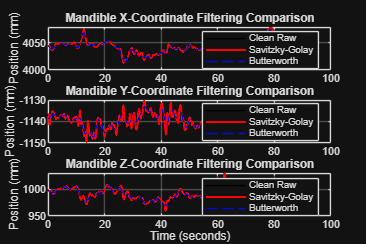

figure('Name', 'Filtering Comparison', 'Position', [200, 100, 1200, 800]);

subplot(3,1,1);
plot(tMotion, Mandible_clean(:,1), 'k-', 'LineWidth', 0.5); hold on;
plot(tMotion, filteredMandible(:,1), 'r-', 'LineWidth', 1.5);
plot(tMotion, butterworthMandible(:,1), 'b--', 'LineWidth', 1);
title('Mandible X-Coordinate Filtering Comparison');
ylabel('Position (mm)');
legend('Clean Raw', 'Savitzky-Golay', 'Butterworth', 'Location', 'best');
grid on;

subplot(3,1,2);
plot(tMotion, Mandible_clean(:,2), 'k-', 'LineWidth', 0.5); hold on;
plot(tMotion, filteredMandible(:,2), 'r-', 'LineWidth', 1.5);
plot(tMotion, butterworthMandible(:,2), 'b--', 'LineWidth', 1);
title('Mandible Y-Coordinate Filtering Comparison');
ylabel('Position (mm)');
legend('Clean Raw', 'Savitzky-Golay', 'Butterworth', 'Location', 'best');
grid on;

subplot(3,1,3);
plot(tMotion, Mandible_clean(:,3), 'k-', 'LineWidth', 0.5); hold on;
plot(tMotion, filteredMandible(:,3), 'r-', 'LineWidth', 1.5);
plot(tMotion, butterworthMandible(:,3), 'b--', 'LineWidth', 1);
title('Mandible Z-Coordinate Filtering Comparison');
xlabel('Time (seconds)');
ylabel('Position (mm)');
legend('Clean Raw', 'Savitzky-Golay', 'Butterworth', 'Location', 'best');
grid on;

## 6. Analyze residuals

fprintf('Analyzing filtering residuals...\n');

Analyzing filtering residuals...


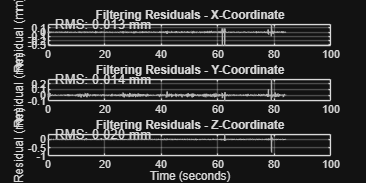


residualMandible = Mandible_clean - filteredMandible;

figure('Name', 'Filtering Residuals', 'Position', [300, 100, 1200, 600]);
subplot(3,1,1);
plot(tMotion, residualMandible(:,1), 'Color', [0.7 0.7 0.7]);
title('Filtering Residuals - X-Coordinate');
ylabel('Residual (mm)');
grid on;
rms_x = sqrt(mean(residualMandible(:,1).^2));
text(0.02, 0.95, sprintf('RMS: %.3f mm', rms_x), 'Units', 'normalized', 'FontSize', 10);

subplot(3,1,2);
plot(tMotion, residualMandible(:,2), 'Color', [0.7 0.7 0.7]);
title('Filtering Residuals - Y-Coordinate');
ylabel('Residual (mm)');
grid on;
rms_y = sqrt(mean(residualMandible(:,2).^2));
text(0.02, 0.95, sprintf('RMS: %.3f mm', rms_y), 'Units', 'normalized', 'FontSize', 10);

subplot(3,1,3);
plot(tMotion, residualMandible(:,3), 'Color', [0.7 0.7 0.7]);
title('Filtering Residuals - Z-Coordinate');
xlabel('Time (seconds)');
ylabel('Residual (mm)');
grid on;
rms_z = sqrt(mean(residualMandible(:,3).^2));
text(0.02, 0.95, sprintf('RMS: %.3f mm', rms_z), 'Units', 'normalized', 'FontSize', 10);

## 7. Enhanced Coordinate Transformation

fprintf('\n=== Coordinate Transformation ===\n');


=== Coordinate Transformation ===



% Pre-allocate memory for calibrated data
calibratedFrontal = zeros(num_points, 3);
calibratedMaxilla = zeros(num_points, 3);
calibratedMandible = zeros(num_points, 3);
calibratedThyCart = zeros(num_points, 3);

% Loop through every frame
for i = 1:num_points
    % Translation: Define the origin at the nasal marker
    origin = filteredNasal(i, :);
    
    % Translate all points relative to origin
    frontal_translated = filteredFrontal(i, :) - origin;
    maxilla_translated = filteredMaxilla(i, :) - origin;
    mandible_translated = filteredMandible(i, :) - origin;
    thycart_translated = filteredThyCart(i, :) - origin;
    
    % Define new coordinate system
    % 1. Define z-axis using [Nasal, Frontal] vector
    frontal_dist = norm(frontal_translated);
    if frontal_dist < 1e-6
        warning('Frame %d: Frontal marker too close to Nasal marker', i);
        k_new = [0, 0, 1]; % Default z-axis
    else
        k_new = frontal_translated / frontal_dist;
    end
    
    % 2. Find the component of global x-axis that's perpendicular to k_new
    global_x = [1, 0, 0];
    proj_x_on_k = dot(global_x, k_new) * k_new;
    j_new_temp = global_x - proj_x_on_k;
    
    % Check if global x is too close to k_new (nearly parallel)
    if norm(j_new_temp) < 1e-5
        % If so, use global y-axis as alternative
        global_y = [0, 1, 0];
        proj_y_on_k = dot(global_y, k_new) * k_new;
        j_new_temp = global_y - proj_y_on_k;
    end
    
    % Normalize to get unit vector
    j_new = j_new_temp / norm(j_new_temp);
    
    % 3. Create x-axis using cross product to ensure perfect orthogonality
    i_new = cross(j_new, k_new);
    
    % Project points to new coordinate system
    calibratedFrontal(i, :) = [dot(frontal_translated, i_new), ...
                              dot(frontal_translated, j_new), ...
                              dot(frontal_translated, k_new)];
    
    calibratedMandible(i, :) = [dot(mandible_translated, i_new), ...
                               dot(mandible_translated, j_new), ...
                               dot(mandible_translated, k_new)];
    
    calibratedMaxilla(i, :) = [dot(maxilla_translated, i_new), ...
                              dot(maxilla_translated, j_new), ...
                              dot(maxilla_translated, k_new)];
    
    calibratedThyCart(i, :) = [dot(thycart_translated, i_new), ...
                              dot(thycart_translated, j_new), ...
                              dot(thycart_translated, k_new)];
end

fprintf('✓ Coordinate transformation completed\n');

✓ Coordinate transformation completed


## 8. Calculate Velocities

fprintf('\n=== Velocity Calculation ===\n');


=== Velocity Calculation ===



% Calculate velocities using central difference
dt = 1/FsMotion;

% Function to calculate velocity with proper boundary handling
function velocity = calculate_velocity(position, dt)
    velocity = zeros(size(position));
    
    for dim = 1:3
        pos = position(:, dim);
        vel = zeros(size(pos));
        
        % Forward difference for first point
        vel(1) = (pos(2) - pos(1)) / dt;
        
        % Central difference for middle points
        for i = 2:length(pos)-1
            vel(i) = (pos(i+1) - pos(i-1)) / (2*dt);
        end
        
        % Backward difference for last point
        vel(end) = (pos(end) - pos(end-1)) / dt;
        
        velocity(:, dim) = vel;
    end
end

% Calculate velocities for all markers
velocityMandible = calculate_velocity(calibratedMandible, dt);
velocityMaxilla = calculate_velocity(calibratedMaxilla, dt);
velocityThyCart = calculate_velocity(calibratedThyCart, dt);

% Calculate speed (magnitude of velocity)
speedMandible = sqrt(sum(velocityMandible.^2, 2));
speedMaxilla = sqrt(sum(velocityMaxilla.^2, 2));
speedThyCart = sqrt(sum(velocityThyCart.^2, 2));

fprintf('✓ Velocity calculations completed\n');

✓ Velocity calculations completed


## 9. Enhanced Visualization of Results

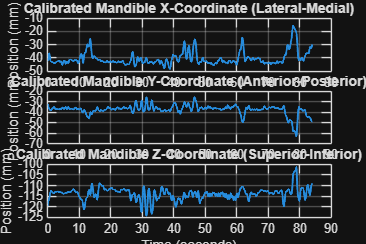

figure('Name', 'Calibrated Position Data', 'Position', [400, 100, 1200, 800]);

subplot(3,1,1);
plot(tMotion, calibratedMandible(:,1), 'LineWidth', 1.5);
title('Calibrated Mandible X-Coordinate (Lateral-Medial)');
ylabel('Position (mm)');
grid on;

subplot(3,1,2);
plot(tMotion, calibratedMandible(:,2), 'LineWidth', 1.5);
title('Calibrated Mandible Y-Coordinate (Anterior-Posterior)');
ylabel('Position (mm)');
grid on;

subplot(3,1,3);
plot(tMotion, calibratedMandible(:,3), 'LineWidth', 1.5);
title('Calibrated Mandible Z-Coordinate (Superior-Inferior)');
xlabel('Time (seconds)');
ylabel('Position (mm)');
grid on;

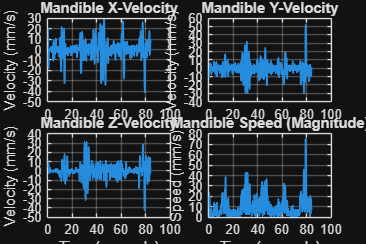


% Velocity visualization
figure('Name', 'Velocity Analysis', 'Position', [500, 100, 1200, 800]);

subplot(2,2,1);
plot(tMotion, velocityMandible(:,1), 'LineWidth', 1.5);
title('Mandible X-Velocity');
ylabel('Velocity (mm/s)');
grid on;

subplot(2,2,2);
plot(tMotion, velocityMandible(:,2), 'LineWidth', 1.5);
title('Mandible Y-Velocity');
ylabel('Velocity (mm/s)');
grid on;

subplot(2,2,3);
plot(tMotion, velocityMandible(:,3), 'LineWidth', 1.5);
title('Mandible Z-Velocity');
xlabel('Time (seconds)');
ylabel('Velocity (mm/s)');
grid on;

subplot(2,2,4);
plot(tMotion, speedMandible, 'LineWidth', 1.5);
title('Mandible Speed (Magnitude)');
xlabel('Time (seconds)');
ylabel('Speed (mm/s)');
grid on;

## 10. Summary Statistics

fprintf('\n=== Motion Summary Statistics ===\n');


=== Motion Summary Statistics ===



% Function to calculate motion statistics
function print_motion_stats(name, position, velocity, speed)
    fprintf('%s Statistics:\n', name);
    fprintf('  Position Range: X=[%.2f, %.2f], Y=[%.2f, %.2f], Z=[%.2f, %.2f] mm\n', ...
        min(position(:,1)), max(position(:,1)), ...
        min(position(:,2)), max(position(:,2)), ...
        min(position(:,3)), max(position(:,3)));
    fprintf('  Max Speed: %.2f mm/s\n', max(speed));
    fprintf('  Mean Speed: %.2f mm/s\n', mean(speed));
    fprintf('  RMS Velocity: X=%.2f, Y=%.2f, Z=%.2f mm/s\n', ...
        sqrt(mean(velocity(:,1).^2)), sqrt(mean(velocity(:,2).^2)), sqrt(mean(velocity(:,3).^2)));
    fprintf('\n');
end

print_motion_stats('Mandible', calibratedMandible, velocityMandible, speedMandible);

Mandible Statistics:
  Position Range: X=[-48.30, -15.59], Y=[-62.60, -25.46], Z=[-124.25, -101.30] mm
  Max Speed: 74.80 mm/s
  Mean Speed: 10.41 mm/s
  RMS Velocity: X=8.66, Y=8.28, Z=6.98 mm/s



print_motion_stats('Maxilla', calibratedMaxilla, velocityMaxilla, speedMaxilla);

Maxilla Statistics:
  Position Range: X=[-14.37, 11.49], Y=[-14.43, 7.46], Z=[-65.92, -58.45] mm
  Max Speed: 41.24 mm/s
  Mean Speed: 6.49 mm/s
  RMS Velocity: X=6.69, Y=5.81, Z=2.39 mm/s



print_motion_stats('Thyroid Cartilage', calibratedThyCart, velocityThyCart, speedThyCart);

Thyroid Cartilage Statistics:
  Position Range: X=[-88.97, -33.43], Y=[-102.35, -40.47], Z=[-137.76, -106.76] mm
  Max Speed: 135.10 mm/s
  Mean Speed: 13.21 mm/s
  RMS Velocity: X=12.11, Y=11.67, Z=8.27 mm/s




% 11: Save Results
fprintf('=== Saving Results ===\n');

=== Saving Results ===



% Save comprehensive results
save('./ProcessedData/Motion.mat', ...
    'filteredFrontal', 'filteredNasal', 'filteredMaxilla', 'filteredMandible', 'filteredThyCart', ...
    'calibratedFrontal', 'calibratedMaxilla', 'calibratedMandible', 'calibratedThyCart', ...
    'velocityMandible', 'velocityMaxilla', 'velocityThyCart', ...
    'speedMandible', 'speedMaxilla', 'speedThyCart', ...
    'outlier_indices', 'FsMotion', 'tMotion', 'Fc');

fprintf('✓ All results saved to MotionData.mat\n');

✓ All results saved to MotionData.mat


fprintf('✓ Analysis complete!\n');

✓ Analysis complete!
